clear; clc;
mFile = '..\mask2m_16_16.mat';
load(mFile); % mask2m 304x304x361

% Get the dimensions of the data
[h, w, c] = size(mask2m);


% Reshape the data into a 2D matrix
x = reshape(mask2m, h * w, c);


% Calculate the FFT 
fftx = fft(x, [], 2);

% Calculate the magnitude (abs) of fftx
fftEspec = abs(fftx).^2;

% Get the indices of the most important frequencies
[Espec, fftEspecOrder] = sort(fftEspec, 2, 'descend');
Espec = cumsum(Espec, 2)./(sum(Espec, 2)*ones([1 361]));

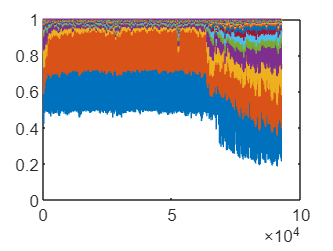

% Remove duplicate entries and keep only unique data
top_10_unique_indices = unique(top_10_indices(:));

% Save the top 10 unique indices in to a CSV file
csvwrite('top_10_indices.csv', top_10_unique_indices);

% Plot the highest and most common frequency points
figure;
plot(highest_freq_point, 'ro', 'MarkerFaceColor', 'r');
hold on;
plot(most_common_freq_point, 'bo', 'MarkerFaceColor', 'b');
xlabel('Index');
ylabel('Magnitude');
title('Highest and Most Common Frequency Points');
legend('Highest Frequency Point', 'Most Common Frequency Point');

% Calculate the mean value of ffty
fftM = mean(ffty, 1);

% Find the indices of the top 10 with the highest mean value
[~, Morder] = sort(fftM, 'descend');
top_10_mean_indices = Morder(1:10);

% Display the top 10 mean indices
disp('Top 10 Indices with Highest Mean:');
disp(top_10_mean_indices);
